# Analysis

## Import saved dataset

clearvars;
% eeglab; close;
trials = {'001-AO', '002-AO', '003-AO'};

filepath = 'C:\\Users\\anhtn\\OneDrive - PennO365\\Documents\\GitHub\\analysis\\Datasets\\';

ALLEEG = cell(1,3);
for i=1:length(trials)
    filename = [trials{i} '-preprocessed.set']; % manually type to select dataset
    ALLEEG{i} = pop_loadset('filename', filename, 'filepath', filepath);
end

pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\001-AO-preprocessed.set ...
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\002-AO-preprocessed.set ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\003-AO-preprocessed.set ...
eeg_checkset: recomputing the ICA activation matrix ...



trial_N = 3;
EEG = ALLEEG{trial_N};
% plot_folder = ['plot-' trials(trial_N) '\\' ];
output_plot_path = [filepath 'output' '\\'];

###  Parameters

chan_names = {'C3', 'C4'};
RH_cluster = {'C4', 'FC2', 'FC6', 'F4'};
LH_cluster = {'C3', 'FC5', 'FC1', 'F3'};
all_elec = [RH_cluster LH_cluster];
elec_plot = {all_elec}; % plot PSD of EEG at all relevant electrodes

theta_band = {4:8};
alpha_l_band = {8:10};
alpha_h_band = {10:13};
alpha_band = {8:13};
beta_band = {13:30};
freq_bands = [theta_band, alpha_band, beta_band];
band_names = ["theta" "alpha" "beta"];
band_colors = ['b','r','g'];
freq_bands_bl = [theta_band,  alpha_band, beta_band];

freqs_array = [4,8,10,13,30];

markerVal_string = ["10" "11" "12" "13" "14" "15" "16" "17"...
    "20" "21" "22" "23" "24" "25" "26" "27" ...
    "30" "31" "32" "33" "34" "35" "36" "37" ...
    "40" "41" "42" "43" "44" "45" "46" "47"];
markerVal_num = [10  11  12  13  14  15  16  17 20  21  22  23  24  25  26  27  30  31  32  33  34  35  36  37  40  41  42  43  44  45  46  47];
markerLabel = ["human-left", "human-right", "robot-left", "robot-right"];
% markerColor = ["b", "c", "r","m" ];
markerColor = ["b", "b", "r","r" ];
markerCurveStyle = ["-", "--", "-","--" ];

actor_pair = {[1 2], [3 4]};
side_pair = {[1 3], [2 4]};
actor_pair_names = cell(1,2);
for i = 1:2
    actor_pair_names{i} = [markerLabel(actor_pair{i})];
end
side_pair_names = cell(1,2);
for i = 1:2
    side_pair_names{i} = [markerLabel(side_pair{i})];
end
actions_type1 = [3 4 5 6]; % first sec still hand
actions_type2 = [0 1 2 7]; % first sec moving hand (pre-action)
actions = {actions_type1, actions_type2};
actions_type_names = {'1st-sec still hand', '1st-sec pre-action'};
freqfac = 2;
timesout_stim = 400;

% base_tlen = [0 8];
% cond_plot_spectra(EEG, {'1000'}, [5 6], ...
%         freqs_array, {{'C3', 'C4'}}, freqfac, "", [], 'on');

## Check correlation: comparing power spectrum of 1-sec window with that of full-length baseline epochs (C3)

**Time window which has the highest correlation (averaged across 3 bands) with the spectra (PSD) averaged across all baseline (8sec) epochs - will be used for further analysis**

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.7666    0.8166    0.7727    0.8329    0.7529    0.9022    0.9381    0.7075


idx_base = 7

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), k

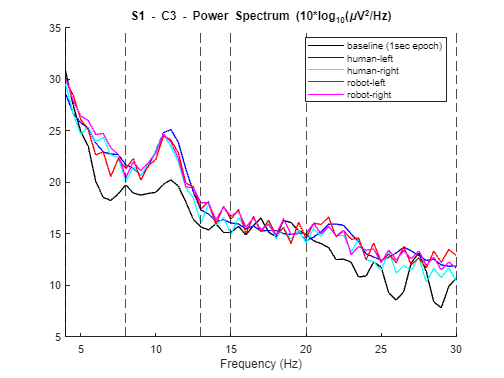

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 25 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 25 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 25 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 25 channel(s)...


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.7405    0.7659    0.5040    0.9447    0.8082    0.8254    0.7671    0.8343


idx_base = 4

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 m

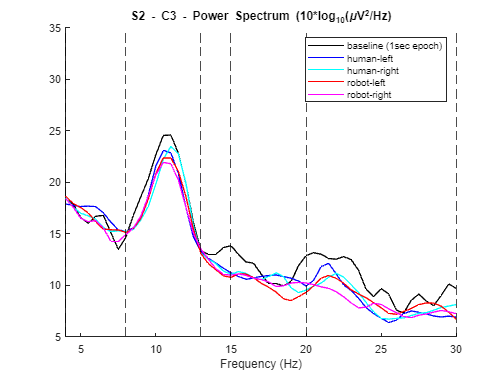

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.7153    0.7605    0.7524    0.5992    0.7172    0.7990    0.5722    0.6119


idx_base = 6

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), k

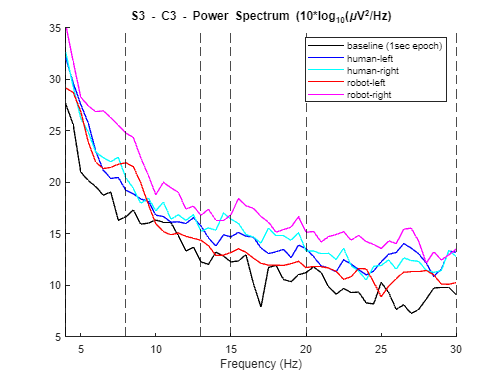

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 24 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 24 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 24 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 24 channel(s)...


ersp_C3_subj = cell(1, 3);
ersp_mean_C3_subj = cell(1,3);

for trial_N = 1:3
    EEG = ALLEEG{trial_N};

    base_tlen = [0 8];
    [spectra_base, ~, ~] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3'}}, freqfac, "", [], 'off');


    corrcoef_cell = [];
    for t = base_tlen(1)+1:base_tlen(2)
        tlen = t-1:t;
        EEG_cond_epoch = cond_epoch(EEG, {'1000'}, tlen);
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
        [spectra,freqs,~,~,~] = pop_spectopo(EEG_cond_chan, 1, [tlen(1) tlen(end)]*1000, 'EEG',...
            'freq', freqs_array, 'plot', 'off', 'verbose', 'off', 'freqfac', freqfac);
        R = 0;
        for f = 1:length(freq_bands_bl)
            spectra_band = spectra(1, freqs >= freq_bands_bl{f}(1) & freqs <= freq_bands_bl{f}(end));
            spectra_base_band = spectra_base( freqs >= freq_bands_bl{f}(1) & freqs <= freq_bands_bl{f}(end));
            R_band = corrcoef(spectra_band, spectra_base_band);
            R = R + R_band(1,2);
        end
        R = R/3;
        corrcoef_cell = [corrcoef_cell R];
    end
    corrcoef_cell
    [~, idx_base] = max(corrcoef_cell)

    base_tlen = [idx_base-1 idx_base];
    % cond_plot_spectra(EEG, {'1000'}, base_tlen, freqs_array, {{'C3', 'C4'}},freqfac, "", [], 'on');

    % Compute Spectrogram of the stim epoch: time-frequency transform (using newtimef with option 'Baseline' being NaN) (C3)
    % Angelini 2018
    base_tlen = [idx_base-1 idx_base];
    [spectra_base, freqs_base, specstd_base] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3'}}, freqfac, "", [], 'off');
    spectra_base = spectra_base(freqs_base >= 4 & freqs_base <= 30);
    % spectra_base_abs = 10.^(spectra_base./10);

    figure(); title("S"+ num2str(trial_N)+" - C3 - Power Spectrum (10*log_{10}(\muV^{2}/Hz)");
    hold on
    plot(4:1/freqfac:30, spectra_base + 10*log10(128/2),'DisplayName', 'baseline (1sec epoch)', 'Color','k')

    stim_tlen = [-0.5 4];
    for i=1:4
        [spectra_stim, freqs_stim, ~] = cond_plot_spectra(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
            freqs_array, {{'C3'}}, freqfac, "", [], 'off');
        spectra_stim = spectra_stim(freqs_stim >= 4 & freqs_stim <= 30);
        spectra_stim_abs = 10.^(spectra_stim./10);

        plot(4:1/freqfac:30, spectra_stim+ 10*log10(128/2),'DisplayName', markerLabel(i), 'Color',markerColor(i))
    end
    xlabel('Frequency (Hz)')
    xline([4 8 13 15 20 30], '--', 'Color', 'black', 'HandleVisibility','off')
    ylim([5 35]); xlim([4 30])
    hold off; legend({})

    % Compute ERD/S (Grandchamp and Delorme 2011)
    % stim_tlen = [-1 4];
    ersp_mean_C3 = cell(1,4);
    ersp_C3 = cell(1,4);

    for i=1:4
        EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen);
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
        % figure(); title('stim')
        [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
            pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
            'freqs', [4 30],'nfreqs', length(4:1/freqfac:30), 'plotitc', 'off', 'plotersp', 'off', ...
            'verbose', 'off', 'baseline', NaN, 'timesout', timesout_stim);

        % Baseline correction
        ersp_baseln = zeros(size(ersp));
        for row = 1:height(ersp)
            ersp_baseln(row, :) = ersp(row, :) - (spectra_base(row) + 10*log10(128/2));
        end
        % ersp_baseln = 10.^(ersp_baseln/10); %convert from 10log10 to absolute
        ersp_baseln = ersp_baseln/10; %convert to log10 scale
        ersp_baseln_mean = mean(ersp_baseln, 2);

        ersp_C3{i} = ersp_baseln;
        ersp_mean_C3{i} = ersp_baseln_mean;

        % figure();
        % subplot(1,4,1:3); hold on
        % % imagesc(times, freqs, 10.^(ersp_baseln/10)); box on
        % imagesc(times, freqs, ersp_baseln); box on
        % xline([0 1000], '--');
        % yline([8.5 12 14 17.5 18.5 24], '--', 'Color', 'black')
        % max_val = max(abs(ersp_baseln(:))); clim([-max_val max_val])
        % axis xy; colormap(jet(256)); colorbar; xlabel('Time (ms)'); ylabel('Frequency (Hz)');
        % ylim([4 30]); xlim([min(times) max(times)]);
        % title('ERSP - C3 - '+ markerLabel(i))
        % hold off
        % subplot(1,4,4); hold on; title('Power Ratio')
        % plot(ersp_baseln_mean, freqs)
        % yline([8.5 12 14 17.5 18.5 24], '--', 'Color', 'black'); xline(0, '--')
        % ylim([4 30])%; xlim([0 2]); xticks(0:0.5:2)
        % set ( gca, 'xdir', 'reverse' ); box on
        % hold off
    end
        
    ersp_C3_subj{trial_N} = ersp_C3;
    ersp_mean_C3_subj{trial_N} = ersp_mean_C3;
end

times_stim = times;

Note: Beta rhythms (13–30 Hz) are present throughout the motor system in the absence of movement.

### Plot ERDS among subjects, average across stimulus epochs

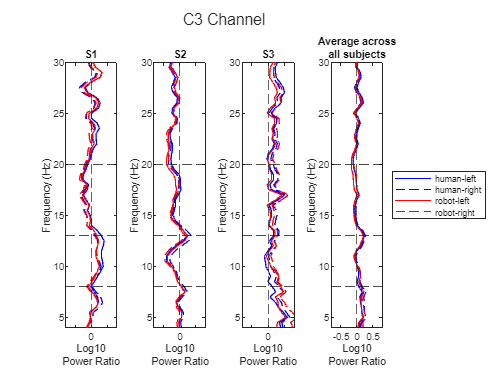

f = figure();
t = tiledlayout(1,4);
title(t, 'C3 Channel')
for trial_N = 1:3
    ersp_mean_C3 = ersp_mean_C3_subj{trial_N};
    nexttile; hold on; title("S"+num2str(trial_N))
    for i=1:4
        plot(ersp_mean_C3{i}, freqs, 'DisplayName', markerLabel(i), 'Color',markerColor(i), "LineStyle", markerCurveStyle(i))
    end
    yline([8 13 20], '--', 'Color', 'black', 'HandleVisibility','off');
    xline(0, '--', 'HandleVisibility','off')
    ylim([4 30]); ylabel('Frequency (Hz)'); xlim([-0.8 0.8])
    xlabel("Log10"+newline+"Power Ratio");
    % set ( gca, 'xdir', 'reverse' ); 
    box on

    hold off
end

nexttile; title("Average across"+newline+"all subjects")
hold on
for i = 1:4
    ersp_mean_allsubj= [];
    for trial_N = 1:3
        ersp_mean_C3 = ersp_mean_C3_subj{trial_N};
        ersp_mean_allsubj = [ersp_mean_allsubj ersp_mean_C3{i}];
    end

    plot(mean(ersp_mean_allsubj, 2), freqs, 'DisplayName', markerLabel(i), 'Color',markerColor(i), "LineStyle", markerCurveStyle(i))
end
legend('Location','eastoutside', 'AutoUpdate','off');
yline([8 13 20], '--', 'Color', 'black', 'HandleVisibility','off');
xline(0, '--', 'HandleVisibility','off')
ylim([4 30]); ylabel('Frequency (Hz)'); xlim([-0.8 0.8])
xlabel("Log10"+newline+"Power Ratio");
% set ( gca, 'xdir', 'reverse' ); 
box on

hold off



plotfilename = 'C3_allersp';
% matlab2tikz('figurehandle',f,'filename', [output_plot_path plotfilename '.tex'])

### Compute ERDS for channel C4

Run the same steps: find the baseline time window with highest correlation of power spectrum with the full-length baseline epochs; compute power spectrum and spectrogram of stim epochs; compute ERD/S

001-AO-preprocessed.set


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.8563    0.9338    0.9069    0.5840    0.8284    0.9270    0.7359    0.9564


idx_base = 8

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'key', 'val' par

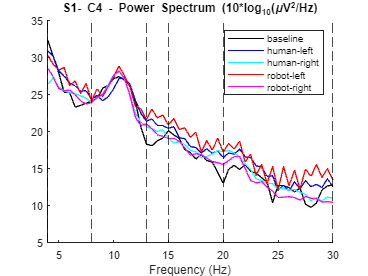

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 25 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 25 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 25 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 25 channel(s)...


002-AO-preprocessed.set


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.7299    0.8031    0.8445    0.5317    0.8059    0.8069    0.8070    0.8565


idx_base = 8

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -50

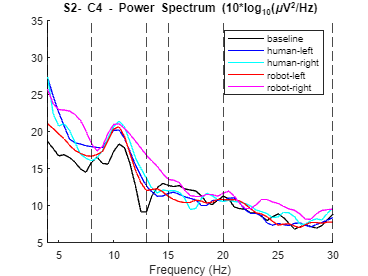

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 31 channel(s)...


003-AO-preprocessed.set


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.6792    0.4598    0.6492    0.6674    0.8072    0.7153    0.3962    0.7646


idx_base = 5

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'key', 'val' par

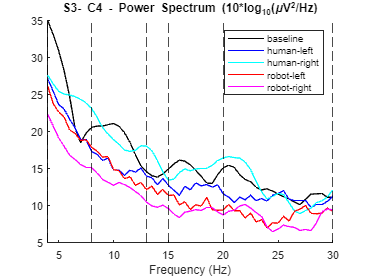

pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 24 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 24 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 24 channel(s)...


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Removing 24 channel(s)...


ersp_C4_subj = cell(1, 3);
ersp_mean_C4_subj = cell(1,3);

for trial_N = 1:3
    EEG = ALLEEG{trial_N};
    disp(EEG.filename)

    base_tlen = [0 8];
    [spectra_base, ~, ~] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C4'}}, freqfac, "", [], 'off');


    corrcoef_cell = [];
    for t = base_tlen(1)+1:base_tlen(2)
        tlen = t-1:t;
        EEG_cond_epoch = cond_epoch(EEG, {'1000'}, tlen);
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C4'});
        [spectra,freqs,~,~,~] = pop_spectopo(EEG_cond_chan, 1, [tlen(1) tlen(end)]*1000, 'EEG',...
            'freq', freqs_array, 'plot', 'off', 'verbose', 'off', 'freqfac', freqfac);
        R = 0;
        for f = 1:length(freq_bands_bl)
            spectra_band = spectra(1, freqs >= freq_bands_bl{f}(1) & freqs <= freq_bands_bl{f}(end));
            spectra_base_band = spectra_base( freqs >= freq_bands_bl{f}(1) & freqs <= freq_bands_bl{f}(end));
            R_band = corrcoef(spectra_band, spectra_base_band);
            R = R + R_band(1,2);
        end
        R = R/3;
        corrcoef_cell = [corrcoef_cell R];
    end
    corrcoef_cell
    [~, idx_base] = max(corrcoef_cell)

    base_tlen = [idx_base-1 idx_base];
    % cond_plot_spectra(EEG, {'1000'}, base_tlen, freqs_array, {{'C3', 'C4'}},freqfac, "", [], 'on');
    %---------------------------------------------------------------
    base_tlen = [idx_base-1 idx_base];
    [spectra_base, freqs_base, specstd_base] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C4'}}, freqfac, "", [], 'off');
    spectra_base = spectra_base(freqs_base >= 4 & freqs_base <= 30);
    spectra_base_abs = 10.^(spectra_base./10);

    f1 = figure;

    figure(f1); title("S"+ num2str(trial_N)+"- C4 - Power Spectrum (10*log_{10}(\muV^{2}/Hz)");
    hold on
    plot(4:1/freqfac:30, spectra_base + 10*log10(128/2),'DisplayName', 'baseline', 'Color','k')

    stim_tlen = [-0.5 4];
    for i=1:4
        [spectra_stim, freqs_stim, ~] = cond_plot_spectra(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
            freqs_array, {{'C4'}}, freqfac, "", [], 'off');
        spectra_stim = spectra_stim(freqs_stim >= 4 & freqs_stim <= 30);
        spectra_stim_abs = 10.^(spectra_stim./10);

        plot(4:1/freqfac:30, spectra_stim+ 10*log10(128/2),'DisplayName', markerLabel(i), 'Color',markerColor(i))
    end
    xlabel('Frequency (Hz)')
    xline([4 8 13 15 20 30], '--', 'Color', 'black', 'HandleVisibility','off')
    ylim([5 35]); xlim([4 30])
    legend(); hold off;

    ersp_mean_C4 = cell(1,4);
    ersp_C4 = cell(1,4);

    % stim_tlen = [0 4];
    for i=1:4
        EEG_cond_epoch = pop_epoch(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen);
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C4'});
        % figure(); title('stim')
        [ersp,itc,powbase,times,freqs,erspboot,itcboot,tfdata] = ...
            pop_newtimef(EEG_cond_chan, 1, 1, stim_tlen*1000, [4 15.36], ...
            'freqs', [4 30],'nfreqs', length(4:1/freqfac:30), 'plotitc', 'off', 'plotersp', 'off', ...
            'verbose', 'off', 'baseline', NaN, 'timesout', timesout_stim);

        % Baseline correction
        ersp_baseln = zeros(size(ersp));
        for row = 1:height(ersp)
            ersp_baseln(row, :) = ersp(row, :) - (spectra_base(row) + 10*log10(128/2));
        end
        % ersp_baseln = 10.^(ersp_baseln/10); %convert from 10log10 to absolute
        ersp_baseln = ersp_baseln/10; %convert to log10 scale
        ersp_baseln_mean = mean(ersp_baseln, 2);

        ersp_C4{i} = ersp_baseln;
        ersp_mean_C4{i} = ersp_baseln_mean;
    end

    ersp_C4_subj{trial_N} = ersp_C4;
    ersp_mean_C4_subj{trial_N} = ersp_mean_C4;
end

### Plot ERDS curves among subjects, average across stimulus epochs

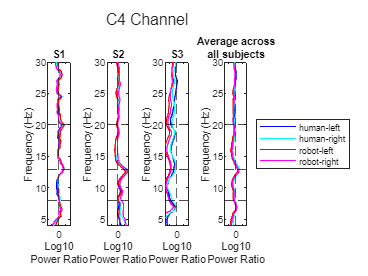

f = figure();
t = tiledlayout(1,4);
title(t, 'C4 Channel')
for trial_N = 1:3
    ersp_mean_C4 = ersp_mean_C4_subj{trial_N};
    nexttile; hold on; title("S"+num2str(trial_N))
    for i=1:4
        plot(ersp_mean_C4{i}, freqs, 'DisplayName', markerLabel(i), 'Color',markerColor(i))
    end
    yline([8 13 20], '--', 'Color', 'black', 'HandleVisibility','off');
    xline(0, '--', 'HandleVisibility','off')
    ylim([4 30]); ylabel('Frequency (Hz)'); xlim([-0.8 0.8])
    xlabel("Log10"+newline+"Power Ratio");
    % set ( gca, 'xdir', 'reverse' ); \
    box on

    hold off
end

nexttile; title("Average across"+newline+"all subjects")
hold on
for i = 1:4
    ersp_mean_allsubj= [];
    for trial_N = 1:3
        ersp_mean_C4 = ersp_mean_C4_subj{trial_N};
        ersp_mean_allsubj = [ersp_mean_allsubj ersp_mean_C4{i}];
    end

    plot(mean(ersp_mean_allsubj, 2), freqs, 'DisplayName', markerLabel(i), 'Color',markerColor(i))
end
legend('Location','eastoutside', 'AutoUpdate','off');
yline([8 13 20], '--', 'Color', 'black', 'HandleVisibility','off');
xline(0, '--', 'HandleVisibility','off')
ylim([4 30]); ylabel('Frequency (Hz)'); xlim([-0.8 0.8])
xlabel("Log10"+newline+"Power Ratio");
% set ( gca, 'xdir', 'reverse' ); 
box on

hold off


plotfilename = 'C4_allersp';
% matlab2tikz('figurehandle',f,'filename', [output_plot_path plotfilename '.tex'])

### Plot ERDS colormap to present temporal info of ERDS

Average across all conditions for each subject


$$dB=10\log_{10} \frac{P_{event} }{P_{baseline} }$$


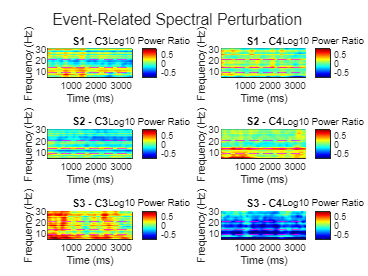

f = figure(); t = tiledlayout(3,2);
title(t, 'Event-Related Spectral Perturbation')

for trial_N = 1:3
    ersp_C3 = ersp_C3_subj{trial_N}; %log10 scale
    ersp_allcond = zeros(size(ersp_C3{1}));
    for i = 1:4
        ersp_allcond = ersp_allcond + ersp_C3{i};
    end
    ersp_allcond = ersp_allcond/4;
    % ersp_allcond = ersp_allcond*10; % convert ERSP to dB

    nexttile; hold on
    imagesc(times, freqs, ersp_allcond); box on
    % xline([0 1000], '--');
    yline([8 13 20], '--', 'Color', 'magenta')
    max_val = max(abs(ersp_allcond(:))); clim([-0.8 0.8])
    axis xy; colormap(jet(256)); h = colorbar; title(h, "Log10 "+"Power Ratio", 'FontSize', 8)
    xlabel('Time (ms)'); ylabel('Frequency (Hz)');
    ylim([4 30]); xlim([min(times) max(times)]);
    title("S"+ num2str(trial_N)+" - C3")
    hold off
    
    %===================
    ersp_C4 = ersp_C4_subj{trial_N};
    ersp_allcond = zeros(size(ersp_C4{1}));
    for i = 1:4
        ersp_allcond = ersp_allcond + ersp_C4{i};
    end
    ersp_allcond = ersp_allcond/4;
    % ersp_allcond = ersp_allcond*10; % convert ERSP to dB

    nexttile; hold on
    imagesc(times, freqs, ersp_allcond); box on
    % xline([0 1000], '--');
    yline([8 13 20], '--', 'Color', 'magenta')
    max_val = max(abs(ersp_allcond(:))); clim([-0.8 0.8])
    axis xy; colormap(jet(256));  h = colorbar; title(h, "Log10 "+"Power Ratio", 'FontSize', 8)
    xlabel('Time (ms)'); ylabel('Frequency (Hz)');
    ylim([4 30]); xlim([min(times) max(times)]);
    title("S"+ num2str(trial_N)+" - C4")
    hold off
end

plotfilename = 'ERSP';
% matlab2tikz('figurehandle',f,'filename', [output_plot_path plotfilename '.tex'])

### Plot all Power spectrum data

markerColor = ["b", "c", "r","m" ];
f_PSD = figure(); t = tiledlayout(3,2, "TileSpacing","tight");
title(t, 'Power Spectrum (10*log_{10}(\muV^{2}/Hz)');

for trial_N = 1:3
    EEG = ALLEEG{trial_N};

    base_tlen = [0 8];
    [spectra_base, ~, ~] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3'}}, freqfac, "", [], 'off');
    corrcoef_cell = [];
    for t = base_tlen(1)+1:base_tlen(2)
        tlen = t-1:t;
        EEG_cond_epoch = cond_epoch(EEG, {'1000'}, tlen);
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C3'});
        [spectra,freqs,~,~,~] = pop_spectopo(EEG_cond_chan, 1, [tlen(1) tlen(end)]*1000, 'EEG',...
            'freq', freqs_array, 'plot', 'off', 'verbose', 'off', 'freqfac', freqfac);
        R = 0;
        for f = 1:3
            spectra_band = spectra(1, freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end));
            spectra_base_band = spectra_base( freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end));
            R_band = corrcoef(spectra_band, spectra_base_band);
            R = R + R_band(1,2);
        end
        R = R/3;
        corrcoef_cell = [corrcoef_cell R];
    end
    corrcoef_cell
    [~, idx_base] = max(corrcoef_cell)

    base_tlen = [idx_base-1 idx_base];

    [spectra_base, freqs_base, ~] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C3'}}, freqfac, "", [], 'off');
    spectra_base = spectra_base(freqs_base >= 4 & freqs_base <= 30);

    nexttile; hold on; title("S"+ num2str(trial_N)+" - C3")
    plot(4:1/freqfac:30, spectra_base + 10*log10(128/2),'DisplayName', 'baseline (1sec epoch)', 'Color','k', 'LineStyle','--')

    stim_tlen = [-0.5 4];
    for i=1:4
        [spectra_stim, freqs_stim, ~] = cond_plot_spectra(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
            freqs_array, {{'C3'}}, freqfac, "", [], 'off');
        spectra_stim = spectra_stim(freqs_stim >= 4 & freqs_stim <= 30);
        spectra_stim_abs = 10.^(spectra_stim./10);

        plot(4:1/freqfac:30, spectra_stim+ 10*log10(128/2),'DisplayName', markerLabel(i), 'Color',markerColor(i))
    end
    xlabel('Frequency (Hz)'); ylabel('10*log_{10}(\muV^{2}/Hz')
    % xline([4 8 13 20 30], '--', 'Color', 'black', 'HandleVisibility','off')
    xlim([4 30]); ylim([5 35])
    hold off

    %=============================================
    base_tlen = [0 8];
    [spectra_base, ~, ~] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C4'}}, freqfac, "", [], 'off');


    corrcoef_cell = [];
    for t = base_tlen(1)+1:base_tlen(2)
        tlen = t-1:t;
        EEG_cond_epoch = cond_epoch(EEG, {'1000'}, tlen);
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', {'C4'});
        [spectra,freqs,~,~,~] = pop_spectopo(EEG_cond_chan, 1, [tlen(1) tlen(end)]*1000, 'EEG',...
            'freq', freqs_array, 'plot', 'off', 'verbose', 'off', 'freqfac', freqfac);
        R = 0;
        for f = 1:3
            spectra_band = spectra(1, freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end));
            spectra_base_band = spectra_base( freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end));
            R_band = corrcoef(spectra_band, spectra_base_band);
            R = R + R_band(1,2);
        end
        R = R/3;
        corrcoef_cell = [corrcoef_cell R];
    end
    corrcoef_cell
    [~, idx_base] = max(corrcoef_cell)

    base_tlen = [idx_base-1 idx_base];

    %---------------------------------------------------------------
    base_tlen = [idx_base-1 idx_base];
    [spectra_base, freqs_base, specstd_base] = cond_plot_spectra(EEG, {'1000'}, base_tlen, ...
        freqs_array, {{'C4'}}, freqfac, "", [], 'off');
    spectra_base = spectra_base(freqs_base >= 4 & freqs_base <= 30);
    spectra_base_abs = 10.^(spectra_base./10);

    nexttile; hold on; title("S"+ num2str(trial_N)+" - C4")
    plot(4:1/freqfac:30, spectra_base + 10*log10(128/2),'DisplayName', 'baseline', 'Color','k', 'LineStyle','--')

    stim_tlen = [-0.5 4];
    for i=1:4
        [spectra_stim, freqs_stim, ~] = cond_plot_spectra(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
            freqs_array, {{'C4'}}, freqfac, "", [], 'off');
        spectra_stim = spectra_stim(freqs_stim >= 4 & freqs_stim <= 30);
        spectra_stim_abs = 10.^(spectra_stim./10);

        plot(4:1/freqfac:30, spectra_stim+ 10*log10(128/2),'DisplayName', markerLabel(i), 'Color',markerColor(i))
    end
        xlabel('Frequency (Hz)'); ylabel('10*log_{10}(\muV^{2}/Hz')
    % xline([4 8 13 20 30], '--', 'Color', 'black', 'HandleVisibility','off')
    xlim([4 30]); ylim([5 35])
    hold off

end

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.7666    0.8166    0.7727    0.8329    0.7529    0.9022    0.9381    0.7075


idx_base = 7

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), k

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.8563    0.9338    0.9069    0.5840    0.8284    0.9270    0.7359    0.9564


idx_base = 8

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 25 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), k

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.7405    0.7659    0.5040    0.9447    0.8082    0.8254    0.7671    0.8343


idx_base = 4

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 m

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.7299    0.8031    0.8445    0.5317    0.8059    0.8069    0.8070    0.8565


idx_base = 8

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 m

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.7153    0.7605    0.7524    0.5992    0.7172    0.7990    0.5722    0.6119


idx_base = 6

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), k

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 8000.00 ms (points 1 to 1024)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range   0.00 ms to 1000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 1000.00 ms to 2000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 2000.00 ms to 3000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 3000.00 ms to 4000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 5000.00 ms to 6000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 6000.00 ms to 7000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...


Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_spectopo(): selecting time range 7000.00 ms to 8000.00 ms (points 1 to 128)
Note: duplicate 'chanlocs' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


corrcoef_cell =     0.6792    0.4598    0.6492    0.6674    0.8072    0.7153    0.3962    0.7646


idx_base = 5

pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range 4000.00 ms to 5000.00 ms (points 1 to 128)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 256; overlap 0):
.
pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range -500.00 ms to 4000.00 ms (points 1 to 576)
Note: duplicate 'freq' parameter(s), k

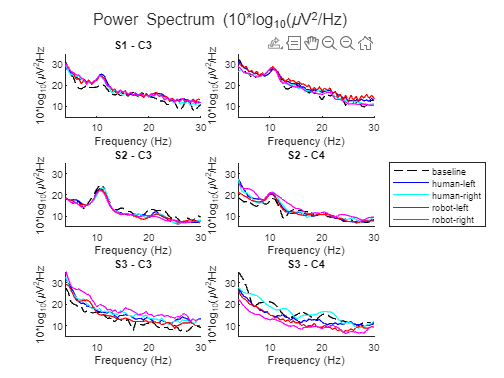


% lgd = legend(); lgd.Layout.Tile ='south'; lgd.NumColumns = 5;

nexttile(4); legend('Location','eastoutside')


plotfilename = 'PSD-1';
% matlab2tikz('figurehandle',f_PSD,'filename', [output_plot_path plotfilename '.tex'])

## Data analysis 

### Correlation of power ratio between conditions for each subject and Plot Correlation

Correlations between each pairs of condition:

f_c3corr = figure(); axgrid = [3 4];
tclMain = tiledlayout(axgrid(1),1,'TileSpacing','compact');
title(tclMain, 'C3 Channel');
tcl = gobjects(1, axgrid(1));
freqs = 4:1/freqfac:30;
for trial_N = 1:3
    disp("S"+trial_N)
    ersp_mean_C3 = ersp_mean_C3_subj{trial_N};
    pairs = {[1 3], [2 4], [1 2], [3 4]};

    tcl(trial_N) = tiledlayout(tclMain,1,axgrid(2),'TileSpacing','compact');
    tcl(trial_N).Layout.Tile = trial_N;
    title(tcl(trial_N), "S"+num2str(trial_N),'fontweight','bold')
    for i=1:4
        disp(num2str(pairs{i}))
        ersp_cond1 = ersp_mean_C3{pairs{i}(1)};
        ersp_cond2 = ersp_mean_C3{pairs{i}(2)};
        [R_cond, P] = corrcoef(ersp_cond1, ersp_cond2)

        nexttile(tcl(trial_N));
        hold on
        for f = 1:3
            plot(ersp_cond1(freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end)), ersp_cond2( freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end)), ...
                '+', 'Color',band_colors(f),  'MarkerSize', 8,'LineWidth', 1, 'DisplayName', band_names(f));
        end
        [coeffs, S] = polyfit(ersp_cond1,ersp_cond2,1);
        h  = refline(coeffs);
        R_squared = 1 - (S.normr/norm(ersp_cond2 - mean(ersp_cond2)))^2
        set(h, 'HandleVisibility','off')
        ylabel(markerLabel(pairs{i}(2)));
        xlabel(markerLabel(pairs{i}(1)));
        text(-0.9,0.8, "r="+num2str(round(R_cond(1,2), 3) ) )

        xlim([-0.8 0.8]); ylim([-0.8 0.8]);
        % xline(0,'--', 'HandleVisibility', 'off')
        %  yline(0,'--', 'HandleVisibility', 'off')
        hold off
    end
end

S1


1  3


R_cond =     1.0000    0.9661
    0.9661    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.9333

2  4


R_cond =     1.0000    0.9462
    0.9462    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.8954

1  2


R_cond =     1.0000    0.8809
    0.8809    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.7760

3  4


R_cond =     1.0000    0.9592
    0.9592    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.9201

S2


1  3


R_cond =     1.0000    0.8825
    0.8825    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.7789

2  4


R_cond =     1.0000    0.9169
    0.9169    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.8408

1  2


R_cond =     1.0000    0.9148
    0.9148    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.8368

3  4


R_cond =     1.0000    0.9311
    0.9311    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.8669

S3


1  3


R_cond =     1.0000    0.6703
    0.6703    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.4492

2  4


R_cond =     1.0000    0.9166
    0.9166    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.8402

1  2


R_cond =     1.0000    0.7916
    0.7916    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.6266

3  4


R_cond =     1.0000    0.8735
    0.8735    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


R_squared = 0.7631

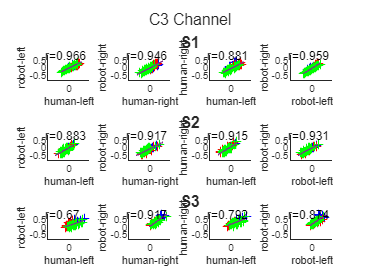

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


% lgd = legend(); lgd.Layout.Tile ='south'; lgd.NumColumns = 3;
plotfilename = 'C3_corr';
matlab2tikz('figurehandle',f_c3corr,'filename', [output_plot_path plotfilename '.tex'])

I dont really know how to inteprete this correlation.

S3 has more ERD at mu band

All subjects have ERD at beta band, this effect is more visible in s2 and s3

S1 has significant ERS at theta band

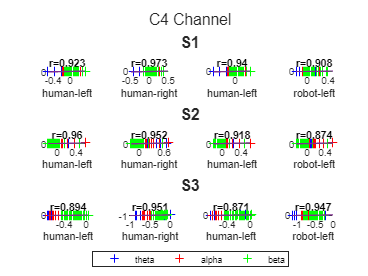

figure; axgrid = [3 4];
tclMain = tiledlayout(axgrid(1),1,'TileSpacing','compact');
title(tclMain, 'C4 Channel');
tcl = gobjects(1, axgrid(1));
freqs = 4:1/freqfac:30;
for trial_N = 1:3
    % disp("S"+trial_N)
    ersp_mean_C4 = ersp_mean_C4_subj{trial_N};
    pairs = {[1 3], [2 4], [1 2], [3 4]};

    tcl(trial_N) = tiledlayout(tclMain,1,axgrid(2),'TileSpacing','compact');
    tcl(trial_N).Layout.Tile = trial_N;
    title(tcl(trial_N), "S"+num2str(trial_N),'fontweight','bold')
    for i=1:4
        % disp(num2str(pairs{i}))
        ersp_cond1 = ersp_mean_C4{pairs{i}(1)};
        ersp_cond2 = ersp_mean_C4{pairs{i}(2)};
        R_cond = corrcoef(ersp_cond1, ersp_cond2);

        nexttile(tcl(trial_N)); title("r="+num2str(round(R_cond(1,2), 3) ))
        hold on
        for f = 1:3
            plot(ersp_cond1(freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end)), ersp_cond2( freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end)), ...
                '+', 'Color',band_colors(f),  'MarkerSize', 8,'LineWidth', 1, 'DisplayName', band_names(f));
        end
        coeffs = polyfit(ersp_cond1,ersp_cond2,1);
        h = refline(coeffs);
        set(h, 'HandleVisibility','off')
        ylabel(markerLabel(pairs{i}(2)));
        xlabel(markerLabel(pairs{i}(1)));
        % text(-0.9,0.8, "r="+num2str(round(R_cond(1,2), 3) ) )

        % xlim([-0.8 0.8]); ylim([-0.8 0.8]);
        % xline(0,'--', 'HandleVisibility', 'off')
        %  yline(0,'--', 'HandleVisibility', 'off')
        hold off
    end
end
lgd = legend(); lgd.Layout.Tile ='south'; lgd.NumColumns = 3;

plotfilename = 'C4_corr';
% matlab2tikz('figurehandle',gcf,'filename', [output_plot_path plotfilename '.tex'])

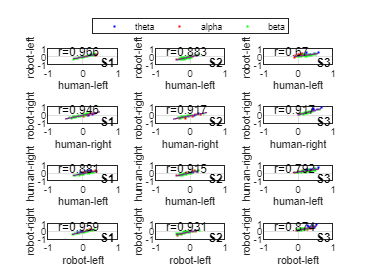

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


f_c3corr = figure; axgrid = [3 4];
tclMain = tiledlayout(4, 3, 'TileSpacing', 'loose', 'TileIndexing','columnmajor');

freqs = 4:1/freqfac:30;
for trial_N = 1:3
    % disp("S"+trial_N)
    ersp_mean_C3 = ersp_mean_C3_subj{trial_N};
    pairs = {[1 3], [2 4], [1 2], [3 4]};

    for i=1:4
        ersp_cond1 = ersp_mean_C3{pairs{i}(1)};
        ersp_cond2 = ersp_mean_C3{pairs{i}(2)};
        R_cond = corrcoef(ersp_cond1, ersp_cond2);

        nexttile; %title("r="+num2str(round(R_cond(1,2), 3) ))
        box on; grid on; hold on
        for f = 1:3
            plot(ersp_cond1(freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end)), ersp_cond2( freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end)), ...
                '.', 'Color',band_colors(f),  'MarkerSize', 5,'LineWidth', 0.7, 'DisplayName', band_names(f));
        end
        coeffs = polyfit(ersp_cond1,ersp_cond2,1);
        h = refline(coeffs);
        set(h, 'HandleVisibility','off')


        ylabel(markerLabel(pairs{i}(2)));
        xlabel(markerLabel(pairs{i}(1)));


        text(-0.7,0.7, "r="+num2str(round(R_cond(1,2), 3) ) )
        text(0.5,-0.7, "S"+trial_N , 'FontWeight', 'bold')

        xlim([-1 1]); ylim([-1 1]); xticks([-1 0 1]); yticks([-1 0 1]);
        hold off
    end
end


nexttile(5); legend('Location','northoutside','Orientation','horizontal')

plotfilename = 'C3_corr';
matlab2tikz('figurehandle',f_c3corr,'filename', [output_plot_path plotfilename '.tex'], ...
    'extraAxisOptions',{'ylabel style={yshift=-10pt}','xlabel style={yshift=5pt}'})

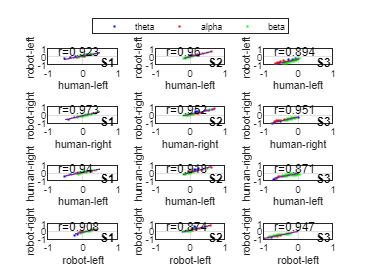

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


    % 'height', '\figureheight', 'width', '\figurewidth', ...

%===============================
f_c4corr = figure; axgrid = [3 4];
tclMain = tiledlayout(4, 3, 'TileSpacing', 'loose', 'TileIndexing','columnmajor');

freqs = 4:1/freqfac:30;
for trial_N = 1:3
    % disp("S"+trial_N)
    ersp_mean_C4 = ersp_mean_C4_subj{trial_N};
    pairs = {[1 3], [2 4], [1 2], [3 4]};

    for i=1:4
        ersp_cond1 = ersp_mean_C4{pairs{i}(1)};
        ersp_cond2 = ersp_mean_C4{pairs{i}(2)};
        R_cond = corrcoef(ersp_cond1, ersp_cond2);

        nexttile; %title("r="+num2str(round(R_cond(1,2), 3) ))
        box on; grid on; hold on
        for f = 1:3
            plot(ersp_cond1(freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end)), ersp_cond2( freqs >= freq_bands{f}(1) & freqs <= freq_bands{f}(end)), ...
                '.', 'Color',band_colors(f),  'MarkerSize', 5,'LineWidth', 0.7, 'DisplayName', band_names(f));
        end
        coeffs = polyfit(ersp_cond1,ersp_cond2,1);
        h = refline(coeffs);
        set(h, 'HandleVisibility','off')


        ylabel(markerLabel(pairs{i}(2)));
        xlabel(markerLabel(pairs{i}(1)));


        text(-0.7,0.7, "r="+num2str(round(R_cond(1,2), 3) ) )
        text(0.5,-0.7, "S"+trial_N , 'FontWeight', 'bold')

        xlim([-1 1]); ylim([-1 1]); xticks([-1 0 1]); yticks([-1 0 1]);
        hold off
    end
end

nexttile(5); legend('Location','northoutside','Orientation','horizontal')

plotfilename = 'C4_corr';
matlab2tikz('figurehandle',f_c4corr,'filename', [output_plot_path plotfilename '.tex'], ...
    'extraAxisOptions',{'ylabel style={yshift=-10pt}','xlabel style={yshift=5pt}'})

    % 'height', '\figureheight', 'width', '\figurewidth', ...

### Angelini 2018

#### Step 1: Confirm if ERDs are significant by comparing log10 power ratio with 0 using one-tail one-sample t-test

Single-subject values were averaged across Observed Hand (LH, RH) and central left and right clusters of electrodes, separately for each perspective and frequency band. Log10 AO ratio data were tested in one-tailed single-sample t tests against 0 (p < 0.05). For each perspective, log10 ratio values significantly lower than 0 indicated significant suppression of central alpha and beta components during AO relative to the baseline.

freqs = 4:0.5:30;
ersp_C3_bands = cell(1,4);

% freq_bands_sig =  {[8.5 12], [14 17.5], [18.5 24]};
% band_names_sig = ["alpha" "beta (14-17.5Hz)" "beta (18.5-24Hz)"];
freq_bands_sig = freq_bands;
band_names_sig = band_names;

Choosing these frequency bands based on observations of ERD at C3. This might be a limitation.


for i = 1:4
    ersp_array = ersp_C3{i} ;
    ersp_bands = [];
    for f = 1:3
        ersp_bands = [ersp_bands; mean(ersp_array(freqs >= freq_bands_sig{f}(1) & freqs <= freq_bands_sig{f}(end), :) )];
    end
    ersp_C3_bands{i} = ersp_bands;
end

"C3" + newline + "One tailed single sample t test" + newline + "Actor"

ans =     "C3
     One tailed single sample t test
     Actor"


for fp = 1:2
    actor_pair_names{fp}
    for f = 1:3
        band_names_sig(f)
        ersp_cond1 = ersp_C3_bands{actor_pair{fp}(1)};
        ersp_cond2 = ersp_C3_bands{actor_pair{fp}(2)};
        [h, p, ~, stats] = ttest((ersp_cond1(f, :)+ ersp_cond2(f,:))/2, zeros(size(ersp_cond1(f, :))), 'Tail', 'left')
    end
end

ans = 1×2 string array
    "human-left"    "human-right"


ans = "theta"

h = 0

p = 1

stats = struct with fields:
    tstat: 62.3876
       df: 399
       sd: 0.1196


ans = "alpha"

h = 0

p = 1

stats = struct with fields:
    tstat: 22.8679
       df: 399
       sd: 0.0878


ans = "beta"

h = 0

p = 1

stats = struct with fields:
    tstat: 33.5379
       df: 399
       sd: 0.1276


ans = 1×2 string array
    "robot-left"    "robot-right"


ans = "theta"

h = 0

p = 1

stats = struct with fields:
    tstat: 39.8261
       df: 399
       sd: 0.2409


ans = "alpha"

h = 0

p = 1

stats = struct with fields:
    tstat: 22.7555
       df: 399
       sd: 0.1735


ans = "beta"

h = 0

p = 1

stats = struct with fields:
    tstat: 19.7162
       df: 399
       sd: 0.1966



newline + "Observed Hand"

ans =     "
     Observed Hand"


for fp = 1:2
    side_pair_names{fp}
    for f = 1:3
        band_names_sig(f)
        ersp_cond1 = ersp_C3_bands{side_pair{fp}(1)};
        ersp_cond2 = ersp_C3_bands{side_pair{fp}(2)};
        [h, p, ~, stats] = ttest((ersp_cond1(f, :)+ ersp_cond2(f,:))/2, zeros(size(ersp_cond1(f, :))), 'Tail', 'left')
    end
end

ans = 1×2 string array
    "human-left"    "robot-left"


ans = "theta"

h = 0

p = 1

stats = struct with fields:
    tstat: 40.5873
       df: 399
       sd: 0.1611


ans = "alpha"

h = 0

p = 1

stats = struct with fields:
    tstat: 15.9396
       df: 399
       sd: 0.1124


ans = "beta"

h = 0

p = 1

stats = struct with fields:
    tstat: 18.5452
       df: 399
       sd: 0.1660


ans = 1×2 string array
    "human-right"    "robot-right"


ans = "theta"

h = 0

p = 1

stats = struct with fields:
    tstat: 67.9209
       df: 399
       sd: 0.1548


ans = "alpha"

h = 0

p = 1

stats = struct with fields:
    tstat: 25.1842
       df: 399
       sd: 0.1654


ans = "beta"

h = 0

p = 1

stats = struct with fields:
    tstat: 29.7725
       df: 399
       sd: 0.1705


All one-sample t-test show significant ERD at the frequency bands of interest.

#### step 1 - C4 channel

freqs = 4:0.5:30;
ersp_C4_bands = cell(1,4);

freq_bands_sig =  {[8.5 12], [14 17.5], [18.5 24]};
band_names_sig = ["alpha" "beta (14-17.5Hz)" "beta (18.5-24Hz)"];

for i = 1:4
    ersp_array = ersp_C4{i} ;
    ersp_bands = [];
    for f = 1:3
        ersp_bands = [ersp_bands; mean(ersp_array(freqs >= freq_bands_sig{f}(1) & freqs <= freq_bands_sig{f}(end), :) )];
    end
    ersp_C4_bands{i} = ersp_bands;
end

disp("C4" + newline + "One tailed single sample t test" + newline + "Actor")

ans =     "C4
     One tailed single sample t test
     Actor"


for fp = 1:2
    disp(actor_pair_names{fp})
    for f = 1:3
        disp(band_names_sig(f))
        ersp_cond1 = ersp_C4_bands{actor_pair{fp}(1)};
        ersp_cond2 = ersp_C4_bands{actor_pair{fp}(2)};
        % compute the mean of log10 power ratio data between conditions
        % (eg. human-right and human-left)
        [h, p, ~, stats] = ttest((ersp_cond1(f, :)+ ersp_cond2(f,:))/2, zeros(size(ersp_cond1(f, :))), 'Tail', 'left')
    end
end

ans = 1×2 string array
    "human-left"    "human-right"


ans = "alpha"

h = 1

p = 1.5368e-176

stats = struct with fields:
    tstat: -50.7807
       df: 399
       sd: 0.2136


ans = "beta (14-17.5Hz)"

h = 1

p = 9.8025e-118

stats = struct with fields:
    tstat: -33.3482
       df: 399
       sd: 0.1934


ans = "beta (18.5-24Hz)"

h = 1

p = 9.9804e-98

stats = struct with fields:
    tstat: -28.2984
       df: 399
       sd: 0.1753


ans = 1×2 string array
    "robot-left"    "robot-right"


ans = "alpha"

h = 1

p = 2.2371e-289

stats = struct with fields:
    tstat: -102.7116
       df: 399
       sd: 0.1372


ans = "beta (14-17.5Hz)"

h = 1

p = 8.4007e-311

stats = struct with fields:
    tstat: -116.7090
       df: 399
       sd: 0.1117


ans = "beta (18.5-24Hz)"

h = 1

p = 0

stats = struct with fields:
    tstat: -140.1953
       df: 399
       sd: 0.0783



disp(newline + "Observed Hand")

ans =     "
     Observed Hand"


for fp = 1:2
    disp(side_pair_names{fp})
    for f = 1:3
        disp(band_names_sig(f))
        ersp_cond1 = ersp_C4_bands{side_pair{fp}(1)};
        ersp_cond2 = ersp_C4_bands{side_pair{fp}(2)};
        [h, p, ~, stats] = ttest((ersp_cond1(f, :)+ ersp_cond2(f,:))/2, zeros(size(ersp_cond1(f, :))), 'Tail', 'left')
    end
end

ans = 1×2 string array
    "human-left"    "robot-left"


ans = "alpha"

h = 1

p = 6.4249e-242

stats = struct with fields:
    tstat: -77.0227
       df: 399
       sd: 0.1689


ans = "beta (14-17.5Hz)"

h = 1

p = 1.2897e-197

stats = struct with fields:
    tstat: -58.2959
       df: 399
       sd: 0.1755


ans = "beta (18.5-24Hz)"

h = 1

p = 4.1608e-222

stats = struct with fields:
    tstat: -68.1070
       df: 399
       sd: 0.1301


ans = 1×2 string array
    "human-right"    "robot-right"


ans = "alpha"

h = 1

p = 1.9891e-197

stats = struct with fields:
    tstat: -58.2252
       df: 399
       sd: 0.2048


ans = "beta (14-17.5Hz)"

h = 1

p = 2.7424e-174

stats = struct with fields:
    tstat: -50.0233
       df: 399
       sd: 0.1851


ans = "beta (18.5-24Hz)"

h = 1

p = 7.2656e-133

stats = struct with fields:
    tstat: -37.4189
       df: 399
       sd: 0.1891


function [ersp_out, times, freqs_out, erspboot_out ] = cond_ersp(EEG, events_cell, tlen, sub_epoch_len, freqs, channels, erspmax, alpha, plottitle, filepath, toPlot)
EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);
if length(channels) == 1
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', channels);
    if alpha ~= 0
        if string(toPlot) == "off"
            [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
                pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
        else
            figure;
            [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
                pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
        end
    else
        figure;
        [ersp_out,~,~,times,freqs_out,erspboot_out,~,~] = ...
            pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
            'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot,'erspmax', erspmax, 'verbose', 'off');
    end

elseif length(channels) == 2
    EEG_cond_chan1 = pop_select( EEG_cond_epoch, 'channel', channels(1));
    EEG_cond_chan2 = pop_select( EEG_cond_epoch, 'channel', channels(2));

    if alpha ~= 0
        if string(toPlot) == "off"
            [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
        else

            figure; sgtitle(plottitle)
            subplot(2,1,1);
            [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            title(string(channels(1)))
            subplot(2,1,2);
            [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'alpha', alpha, 'verbose', 'off');
            title(string(channels(2)))
        end
    else
        if string(toPlot) == "off"
            [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
        else

            figure; sgtitle(plottitle)
            subplot(2,1,1);
            [ersp1,~,~,times,freqs_out,erspboot1,~,~] = ...
                pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            title(string(channels(1)))
            subplot(2,1,2);
            [ersp2,~,~,times,freqs_out,erspboot2,~,~] = ...
                pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'plotersp', toPlot, 'erspmax', erspmax, 'verbose', 'off');
            title(string(channels(2)))
        end
    end
    save_figures(filepath, plottitle, toPlot)
    ersp_out = {ersp1, ersp2}; erspboot_out = {erspboot1, erspboot2};
end

end
%=================================================================
% function

% ===================================================
function [spectra,freqs,specstd] = cond_plot_spectra(EEG, events_cell, tlen, freqs, chanlocs, freqfac, plottitle, filepath, toPlot)
EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);

if length(chanlocs) == 1
    EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', chanlocs{1});
    if string(toPlot) == "on"
        figure; title(plottitle);
    end
    [spectra,freqs,speccomp,contrib,specstd] = pop_spectopo(EEG_cond_chan, 1, tlen*1000, 'EEG', 'freqfac', freqfac,...
        'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');

elseif length(chanlocs) == 2
    EEG_cond_RH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1});
    EEG_cond_LH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1});
    figure; sgtitle(plottitle);
    subplot(211);
    pop_spectopo(EEG_cond_RH, 1, tlen*1000, 'EEG', 'freqfac', freqfac,...
        'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');
    subplot(212);
    pop_spectopo(EEG_cond_LH, 1, tlen*1000, 'EEG', 'freqfac', freqfac,...
        'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on', 'plot', toPlot, 'verbose', 'off');
end
% save_figures(filepath, plottitle, toPlot)
end


%===================================================
function OUTEEG = cond_epoch(EEG, events_cell, tlen)
% events_cell
EEG_epoch = pop_epoch(EEG, events_cell, tlen, 'verbose', 'off');
OUTEEG = pop_rmbase(EEG_epoch, [0 0.5]*1000);

end


function save_figures(filepath, plottitle, toPlot)
if string(toPlot) == "on"
    savefig(fullfile(filepath, plottitle+".fig"));
    saveas(gcf, fullfile(filepath, plottitle+".png"))
end
end


%=================================================================
function plot_ersp_band(times, mean_ersp_bands, std_ersp_bands, cond_num, band_colors, band_names, chan_name)
hold on;
xline(0, 'k--','Alpha', 0.5, 'HandleVisibility', 'off')
yline(0, 'k--','Alpha', 0.5, 'HandleVisibility', 'off')
for i = 1:length(mean_ersp_bands)
    plot(times, mean_ersp_bands{1,i}, 'Color', band_colors(i), 'DisplayName', band_names(i))
    fill([times, fliplr(times)], [mean_ersp_bands{1,i} + std_ersp_bands{1,i}, ...
        fliplr(mean_ersp_bands{1,i} - std_ersp_bands{1,i})], band_colors(i), 'EdgeColor', 'none', ...
        'FaceAlpha', 0.2, 'HandleVisibility', 'off');
end
if cond_num == 1
    title(chan_name);
end
xlim([min(times), max(times)]);
ylabel('ERDS (dB)'); xlabel('time [ms]')
hold off;
end













